# Estudio de Caso No. 1 - COVID19

### Modelo SEIRD

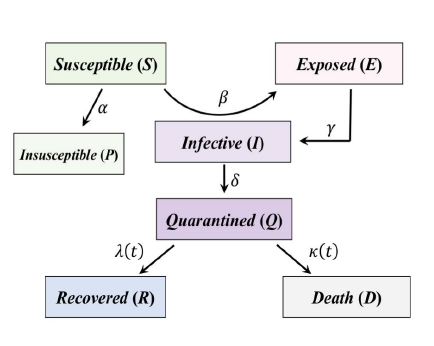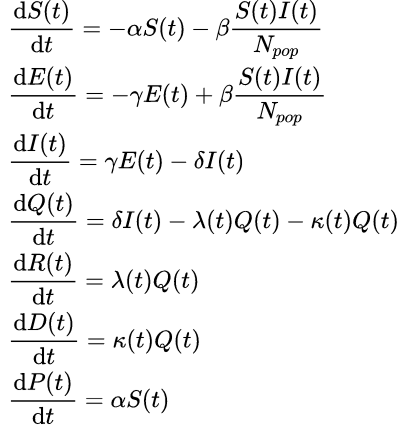

Para esta simulación se generaliza el modelo SEIR clásico incluyendo 3 estados nuevos de enfermedad. En total el modelo generalizado (Ahora llamado SEIQRDP) cuenta con 7 estados:

- S: Casos susceptibles o que aún no han caído en la enfermedad.

- E: Expuestos. Infectados, pero que aún no presentan síntomas y no son capaces de contagiar a otros.

- I: Infectados. Con capacidad de infectar a otros y sin entrar en cuarentena

- Q: Encuarentenados. Confirmados e infectados.

- R: Recuperados.

- D: Muertos o cerrados. 

- P: Inmunes. 

En el caso del COVID-19 no se consideraban tan apropiadas las categorías de inmunidad (P) y cuarentena (Q) no tienen sentido entonces se implementará el denominado SEIRD. 

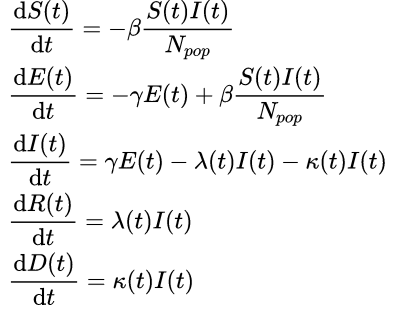

### Obtención y Lectura de Data

clear;

% Número de infectados (I) y muertos (D): Extraído de Our World in Data
% Link: https://ourworldindata.org/coronavirus-source-data
IDData_Address = "https://covid.ourworldindata.org/data/owid-covid-data.csv";

% Número de Recuperados (R): Extraído del repositorio del COVID19 de la universidad
% Johns Hopkins. Link: https://github.com/CSSEGISandData/COVID-19
RData_Address = "https://raw.githubusercontent.com/CSSEGISandData/COVID-19/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_recovered_global.csv";
CData_Address = "https://raw.githubusercontent.com/CSSEGISandData/COVID-19/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_confirmed_global.csv";
DData_Address = "https://raw.githubusercontent.com/CSSEGISandData/COVID-19/master/csse_covid_19_data/csse_covid_19_time_series/time_series_covid19_deaths_global.csv";

% Se guarda la data extraída de los sitios web en 2 CSVs
websave("COVID19_Infected_Deaths.csv", IDData_Address);
websave("COVID19_Recovered.csv", RData_Address);
websave("COVID19_Confirmed.csv", CData_Address);
websave("COVID19_Deaths.csv", DData_Address);

% Se leen los datos guardados en los CSVs
OWID_COVIDData = readtable("COVID19_Infected_Deaths.csv");
RecoveredCOVIDData = readtable("COVID19_Recovered.csv");
ConfirmedCOVIDData = readtable("COVID19_Confirmed.csv");
DeathsCOVIDData = readtable("COVID19_Deaths.csv");
CSSE_COVIDData = {ConfirmedCOVIDData RecoveredCOVIDData DeathsCOVIDData};

### Extracción de Datos Correspondientes a País

Input:

- Pais: Pais del que se desean extraer los datos. Los paises analizados fueron "Italy", "Guatemala" y "China"

Output:

- IDR_Data: Cantidades de infectados (Infected), muertos (Deceased) y recuperados (Recovered).

- IDR_Dates: Fechas que corresponden a cada una de las filas de IDR_Data

NOTA: De los datasets se extrae la parte del IRD del SEIRD. Las dos variables restantes no son necesarias. S se puede calcular como la población total menos el número de infectados (N - I) y E no son necesarias

% Selección del país del que se desea hacer el análisis
Pais = "Italy";

% Fuente de la información. Opciones
%   - OWID: Los casos confirmados y las muertes se extraen de OWID. 
%     Los recuperados se extraen de CSSE
%   - CSSE: Todos los datos (Confirmados, muertes y recuperados) se
%     obtienen de CSSE
Source = "CSSE";

switch Source
    case "OWID"
        % Extracción de la data de los recuperados
        RecoveryData = [RecoveredCOVIDData(1, 5:end); ...                                   % Fila 1: Fechas de la data
                        RecoveredCOVIDData(RecoveredCOVIDData.Var2 == Pais, 5:end)];        % Fila 2: Cantidad de recuperados
        RecoveryData = string(table2cell(RecoveryData)');                                   % Se guardan las dos filas anteriores pero transpuestas y en string
        RecoveryDates = datetime(RecoveryData(:,1)) + years(2000);                          % Primera columna se convierte a tipo "datetime". Debido al formato se le deben sumar 2000 años.
        RecoveryNum = sum(str2double(RecoveryData(:,2:end)),2);
        
        % Extracción de la data de los confirmados (C: total_cases) 
        % y muertos (D: total_deaths)
        GeneralData = OWID_COVIDData(OWID_COVIDData.location == Pais, {'date','total_cases','total_deaths'});
        GeneralData = string(table2cell(GeneralData));
        GeneralDates = datetime(GeneralData(:,1));
        GeneralNum = str2double(GeneralData(:,2:end));
        
        % Merge de las dos tablas según fechas comunes
        [CRD_Dates, DondeEnA, DondeEnB] = intersect(RecoveryDates, GeneralDates);
        CRD_Data = [GeneralNum(DondeEnB,1) RecoveryNum(DondeEnA,:) GeneralNum(DondeEnB,2)];
    
    case "CSSE"
        % Extracción de la data de CSSE
        CRD_Data = [];
        for i = 1:3
            TableData = [CSSE_COVIDData{i}(1, 5:end); ...                                   % Fila 1: Fechas de la data
                         CSSE_COVIDData{i}(CSSE_COVIDData{i}.Var2 == Pais, 5:end)];         % Fila 2: Cantidad de recuperados
            TableData = string(table2cell(TableData)');                                     % Se guardan las dos filas anteriores pero transpuestas y en string
            TableNumbers = sum(str2double(TableData(:,2:end)),2);
            CRD_Data = [CRD_Data TableNumbers];
        end
        
        CRD_Dates = datetime(TableData(:,1)) + years(2000);                                  % Primera columna se convierte a tipo "datetime". Debido al formato se le deben sumar 2000 años.
            
end

% Si el número de casos confirmados es pequeño, es dificil determinar si 
% la cuarentena ha sido implementada rigurosamente o no. Debido a esto se
% comienzan a tomar en cuenta los casos a partir de que lleguen al 10% de
% su valor actual máximo
Threshold = round(0.1 * max(CRD_Data(:,1)));
DatosIgnorados = find(CRD_Data(:,1) <= Threshold);
CRD_Data(DatosIgnorados,:) = [];
CRD_Dates(DatosIgnorados) = [];

% Cálculo de casos activos (A). Dado que involucra dos restas esto puede
% resultar un valores negativos. Dichos valores se igualan a 0
A_Data = CRD_Data(:,1)-CRD_Data(:,2)-CRD_Data(:,3);
A_Data(A_Data < 0) = 0;

### Estimación Inicial de la Tasa de Muerte y Recuperación

Para facilitar la posterior convergencia del algoritmo, se estiman los parámetros de las funciones que dictan los valores de las ecuaciones que modelan la tasa de muerte y recuperación.

% Definición de vector de tiempo "discreto" o con únicamente valores
% enteros (1, 2, 3, etc.) por cada una de las fechas en el dataset
tDiscreto = 0:size(CRD_Dates,1)-1;

% Estimado inicial de los parámetros de Kappa y Lambda
switch Pais
    case "Guatemala"
        LambdaGuess = [0.1 0.5 0.1];    % Tasa de recuperación
        KappaGuess = [0.0022 0.1003];   % Tasa de muerte   
    otherwise
        LambdaGuess = [0.1 0.5 0.1];    % Tasa de recuperación
        KappaGuess = [0.08 0.03];       % Tasa de muerte   
end


#### *Estimado inicial de Kappa (Tasa de Muerte)*

Se realiza un estimado inicial de los parámetros $\kappa_0$ y $\kappa_1$ correspondientes a la ecuación que modela la tasa de muerte como una variable dependiente del tiempo


$$\kappa \left(t\right)=\kappa_0 \;\exp \left(-\kappa_1 t\right)$$


% Se define la función correspondiente a la tasa de muerte
KappaFun = @(Kappa, tiempo) Kappa(1) * exp(-Kappa(2) * tiempo);

% Si hay menos de 20 muertos, la tasa de muerte estimada no genera 
% resultados válidos. Si este es el caso simplemente se salta la 
% estimación de Kappa y se supone que KappaParams == KappaGuess.
if max(CRD_Data(:,3)) > 20
    Options = optimset('TolX',1e-6,'TolFun',1e-6,'Display','off');
    
    % Valores "reales" de Kappa basados en las cantidades reales de muertos
    % (CRD_Data(:,3)) y casos activos (A_Data(2:end)) del país seleccionado.
    DeathRate = (diff(CRD_Data(:,3)) ./ median(diff(tDiscreto'))) ./ A_Data(2:end);
    
    % Un Kappa > 3 es anormalmente alto. Se ignoran los valores mayores a 3
    DeathRate(abs(DeathRate) > 3) = NaN;
    NaNIndices = ~isnan(DeathRate);
    DeathRate = DeathRate(NaNIndices)';
    
    % Se eliminan las X's correspondientes a los valores NaN de Rate.
    XData = tDiscreto(2:end);
    XData = XData(NaNIndices);
    
    % Estimación de Kappa0 y Kappa1 usando "lsqcurvefit()"
    LimiteInf = [0 0];
    LimiteSup = [2 2];
    
    % Sobreescribir límite superior para un país específico
    switch Pais
        case "Guatemala"
            LimiteSup = [0.009 0.1];
    end
    
    KappaParams = lsqcurvefit(@(Params,tiempo) KappaFun(Params,tiempo), KappaGuess, XData, DeathRate, LimiteInf, LimiteSup, Options);

else
    KappaParams = KappaGuess;   
end


#### *Estimado inicial de Lambda (Tasa de Recuperación)*

Se realiza un estimado initial de los parámetros $\lambda_0$, $\lambda_1$ y $\tau$ que forman parte de la ecuación que modela la tasa de recuperación. Existen dos alternativas:


$$\lambda \left(t\right)=\frac{\lambda_0 }{1+\mathrm{exp}\left(-\lambda_1 \left(t-\tau \right)\right)}$$



$$\lambda \left(t\right)=\lambda_0 +\mathrm{exp}\left(-\lambda_1 \left(t+\tau \right)\right)$$


Las $\lambda$ son adimensionales, mientras que $\tau$ tiene tiempo como dimensional. El valor inicial de estas constantes está determinado por una evaluación previa de valores posibles para la tasa de recuperación. La idea detrás de estas funciones es que cuando el tiempo tienda a infinito, el valor de recuperación converja a un valor constante de $\lambda_0$. 

% Si hay menos de 20 recuperados, la tasa de recuperación estimada 
% no genera resultados válidos. Si este es el caso simplemente se salta
% la estimación de Lambda.
if max(CRD_Data(:,2)) > 20
    Options = optimset('TolX',1e-6,'TolFun',1e-6,'Display','off');
    
    % Funciones de lambda
    LambdaFun1 = @(Params, tiempo) Params(1) ./ (1 + exp(-Params(2) * (tiempo - Params(3))));
    LambdaFun2 = @(Params, tiempo) Params(1) + exp(-Params(2) * (tiempo + Params(3)));
    
    % Valores reales de la tasa de recuperación basada en el número de
    % recuperados (CRD_Data(:,2)) y casos activos (A_Data(2:end))
    RecovRate = diff(CRD_Data(:,2)) ./ median(diff(tDiscreto')) ./ A_Data(2:end);
    
    % Un Lambda > 1 o == 0 es anormal. Se ignoran estos valores
    RecovRate(abs(RecovRate) > 1 | abs(RecovRate) == 0) = NaN;
    NaNIndices = ~isnan(RecovRate);
    RecovRate = RecovRate(NaNIndices);
    
    % Se eliminan las X's correspondientes a los valores NaN de la tasa.
    XData = tDiscreto(2:end);
    XData = XData(NaNIndices)';
    
    % Se realizan estimaciones para ambas funciones
    LambdaGuess1 = [0.2 0.1 1]; LambdaGuess2 = [0.2 0.1 min(XData)];
    LimiteInf = [0 0 0];
    LimiteSup = [1 2 100];
    [LambdaParams1,R1] = lsqcurvefit(@(Params,tiempo) LambdaFun1(Params,tiempo), LambdaGuess1, XData, RecovRate, LimiteInf, LimiteSup, Options);
    [LambdaParams2,R2] = lsqcurvefit(@(Params,tiempo) LambdaFun2(Params,tiempo), LambdaGuess2, XData, RecovRate, LimiteInf, LimiteSup, Options);
    
    % Se eligen los parámetros de la función 1 si:
    %   - La norma cuadrada del residuo es menor para la función 1
    %   - Lambda0 es igual a o casi 1
    %   - Lambda1 es igual a o casi 2
    if R1 < R2 || LambdaParams2(1) > 0.99 || LambdaParams2(2) > 1.9
        LambdaParams = LambdaParams1;
        LambdaFun = LambdaFun1;
    else
        LambdaParams = LambdaParams2;
        LambdaFun = LambdaFun2;
    end
    
else
    LambdaFun =  @(Params, tiempo) Params(1) ./ (1 + exp(-Params(2) * (tiempo - Params(3))));
    LambdaParams = LambdaGuess;
end

### Estimación de parámetros de Modelo

% Opciones de lsqcurvfit. Colocar "Display, iter" si se desean ver las
% iteraciones del algoritmo mientras optimiza
Options = optimset('TolX',1e-5,'TolFun',1e-5,'MaxFunEvals',1200,'Display','off');

% Array de tiempo "continuo" con valores "no enteros" y un step de dt. Se
% incrementa artificialmente el número de samples para asegurar
% convergencia
dt = 0.1;
t =  0:dt:size(CRD_Dates,1)-1;

% Estimados iniciales para las constantes
Beta = 0.9;                     % Tasa de infección
TL = 5;                         % Tiempo latente
Gamma = 1 / TL;                 % Inverso del tiempo latente (Frecuencia latente?)

% Población según pais
switch Pais
    case "Guatemala"
        Poblacion = 18050366;
    case "China"
        Poblacion = 1438328434;
    case "Italy"
        Poblacion = 60476307;
    case "Mexico"
        Poblacion = 135692319;
    case "Sweden"
        Poblacion = 10338368;
end

% Condiciones iniciales
Eo = CRD_Data(1,1);                                 % No inicial de expuestos.
Io = A_Data(1);                                     % No inicial de infectados
Ro = CRD_Data(1,2);                                 % No inicial de recuperados
Do = CRD_Data(1,3);                                 % No inicial de muertos
So = Poblacion - (Eo + Io + Ro + Do);               % No inicial de susceptibles
CondInicial = [So Eo Io Ro Do]';

% Array con todos los "Guesses" iniciales para todas las constantes del
% modelo a emplear.
Guess = [Beta Gamma LambdaParams KappaParams];

% Se realiza la estimación de los parámetros
LimiteInf = [0 0 0 0 0 0 0];

% Cambiar límite superior si se desea "Matar a Alpha"
LimiteSup = [3 1 1 5 100 0.009 0.1];
Func = {LambdaFun KappaFun};
ModelParams = lsqcurvefit(@(Params, tiempo) fitModel(Params,tiempo,t,Func,CondInicial), Guess, ...
                          tDiscreto, [A_Data CRD_Data(:,2:3)], LimiteInf, LimiteSup, Options);

### Validación de Resultados

Se repiten los pasos seguidos en la función `fitModel()` pero ahora utilizando los parámetros que fueron estimados previamente. Se grafican los resultados obtenidos para evaluar si el ajuste si fue exitoso.

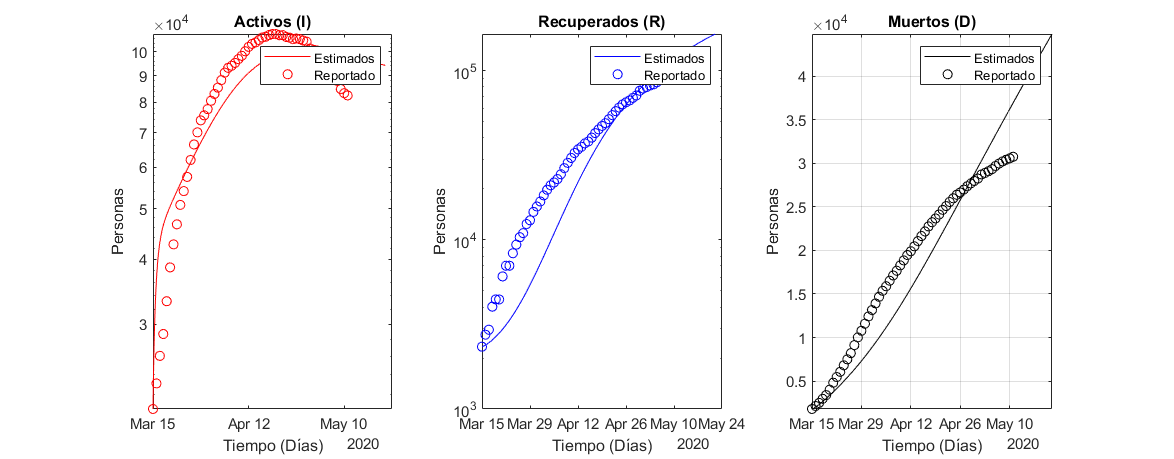

% Límites de graficación para el eje X. Se inicia desde el primer día 
% en el que se registraron casos significativos (Luego de sobrepasar el 
% 10% del valor máximo de casos confirmados) hasta el día de hoy más 
% cierta cantidad de "DiasExtra".
dt = 1/24;                                          % Sampling time = 1 Hora
DiasExtra = 10;                                     % Dias a visualizar luego del día de hoy
PrimerDia = datetime(CRD_Dates(1));                 % Fecha de inicio
UltimoDia = datetime(date) + days(DiasExtra);       % Fecha de finalización

% Vector de tiempo en días, con una diferencia de 1 hora entre cada día
tDias = PrimerDia:dt:UltimoDia;

% Conversión del vector de tiempo en días a valores decimales
tDouble = [0:numel(tDias)-dt] * dt;

% Extracción de los parámetros estimados previamente
Beta = ModelParams(1);
Gamma = ModelParams(2); 
LambdaParams = ModelParams(3:5);
KappaParams = ModelParams(6:7);
                      
% Valores de Lambda y Kappa para cada tiempo en "t"
Lambda = LambdaFun(LambdaParams,tDouble);
Kappa = KappaFun(KappaParams,tDouble);

% Matriz con la evolución de las variables SEIQRDP en el tiempo "t"
Y = zeros(numel(CondInicial), numel(tDouble));
Y(:,1) = CondInicial;

% Definición del modelo a emplear como una función
Modelo = @(Consts, Estado) SEIQRDP(Consts, Estado);

% Desarrollo de modelo
for i = 1:numel(tDouble)-1
    
    % Debido a que Lambda y Kappa cambian con el tiempo, también lo hace el
    % vector de constantes.
    Constantes = [Beta Gamma Lambda(i) Kappa(i)];
    
    % Runge-Kutta de orden 4
    k1 = Modelo(Constantes, Y(:,i));
    k2 = Modelo(Constantes, Y(:,i)+0.5*dt*k1);
    k3 = Modelo(Constantes, Y(:,i)+0.5*dt*k2);
    k4 = Modelo(Constantes, Y(:,i)+k3*dt);
    Y(:,i+1) = Y(:,i) + (1/6)*(k1+2*k2+2*k3+k4)*dt;
end

% Output. Variables 
I = Y(3,:);
R = Y(4,:);
D = Y(5,:);

% Colores
Negro = [0.12 0.12 0.12]

% Gráfica de variables estimadas vs. variables reales
F1 = figure(1); clf;
set(gcf, 'Position', [100, 100, 1024, 400]);
hold on;

subplot(1,3,1);
semilogy(tDias, I, 'r', CRD_Dates, A_Data, 'ro');
ylabel('Personas')
xlabel('Tiempo (Días)')
title("Activos (I)")
legend("Estimados", "Reportado")

subplot(1,3,2);
semilogy(tDias, R, 'b', CRD_Dates, CRD_Data(:,2), 'bo');
ylabel('Personas')
xlabel('Tiempo (Días)')
title("Recuperados (R)")
legend("Estimados", "Reportado")

subplot(1,3,3);
semilogy(tDias, D, 'k', CRD_Dates, CRD_Data(:,3), 'ko');
ylabel('Personas')
xlabel('Tiempo (Días)')
title("Muertos (D)")
legend("Estimados", "Reportado")

set(gcf,'color','w')

grid on
axis tight
set(gca,'yscale','lin');

### Proyección a Futuro

Con las constantes previamente validadas, ahora se puede proceder a proyectar los resultados hacia el futuro. Se coloca la duración de la proyección en dias ("DuraciónDias") y se grafican las variables SEIQRDP. Cabe mencionar que S y P se grafican por separado del resto, ya que estas variables presentan una escala relativamente grande, lo que causa que el resto de variables no pueda apreciarse claramente.

% Límites de graficación para el eje X. Se inicia desde el primer día 
% en el que se registraron casos significativos (Luego de sobrepasar el 
% 10% del valor máximo de casos confirmados) hasta el día de hoy más 
% cierta cantidad de "DiasExtra".
dt = 1/24;                                          % Sampling time = 1 Hora
DuracionDias = 800;                                 % Duración de la proyección en días
PrimerDia = datetime(CRD_Dates(1));                 % Fecha de inicio

Undefined function or variable 'CRD_Dates'.

UltimoDia = PrimerDia + days(DuracionDias);         % Fecha de finalización

% Vector de tiempo en días, con una diferencia de 1 hora entre cada día
tDias = PrimerDia:dt:UltimoDia;

% Conversión del vector de tiempo en días a valores decimales
tDouble = [0:numel(tDias)-dt] * dt;

% Extracción de los parámetros estimados previamente
Beta = ModelParams(1);
Gamma = ModelParams(2);
LambdaParams = ModelParams(3:5);
KappaParams = ModelParams(6:7);
                      
% Valores de Lambda y Kappa para cada tiempo en "t"
Lambda = LambdaFun(LambdaParams,tDouble);
Kappa = KappaFun(KappaParams,tDouble);

% Matriz con la evolución de las variables SEIQRDP en el tiempo "t"
Y = zeros(numel(CondInicial), numel(tDouble));
Y(:,1) = CondInicial;

% Definición del modelo a emplear como una función
Modelo = @(Consts, Estado) SEIQRDP(Consts, Estado);

% Desarrollo de modelo
for i = 1:numel(tDouble)-1
    
    % Debido a que Lambda y Kappa cambian con el tiempo, también lo hace el
    % vector de constantes.
    Constantes = [Beta Gamma Lambda(i) Kappa(i)];
    
    % Runge-Kutta de orden 4
    k1 = Modelo(Constantes, Y(:,i));
    k2 = Modelo(Constantes, Y(:,i)+0.5*dt*k1);
    k3 = Modelo(Constantes, Y(:,i)+0.5*dt*k2);
    k4 = Modelo(Constantes, Y(:,i)+k3*dt);
    Y(:,i+1) = Y(:,i) + (1/6)*(k1+2*k2+2*k3+k4)*dt;
end

% Output de proyección. Se omite el valor de la primera columna para que
% las dimensiones de salida coincidan con las de 
S = Y(1,:);
E = Y(2,:);
I = Y(3,:);
R = Y(4,:);
D = Y(5,:);

% Gráfica EIQRD
figure(2); clf;

hold on; 

switch Pais
    case "Guatemala"
        semilogy(tDias, S, 'b', tDias, E, 'y', tDias, I, 'r', tDias, R, 'g', tDias, D, 'k');
        leg = {'Susceptible (S)','Expuestos (E)', 'Infectados (I)', 'Recuperados (R)', 'Muertos (D)', 'Camas Disponibles (10600)'};
    otherwise
        semilogy(tDias, E, 'y', tDias, I, 'r', tDias, R, 'g', tDias, D, 'k');
        leg = {'Expuestos (E)', 'Infectados (I)', 'Recuperados (R)', 'Muertos (D)', 'Camas Disponibles (10600)'};
end

plot(tDias, ones(size(tDias))*10600, 'b--');
ylabel('Número de Casos')
xlabel('Tiempo (Días)')
leg = {'Expuestos (E)', 'Infectados (I)', 'Recuperados (R)', 'Muertos (D)', 'Camas Disponibles (10600)'};
title({"COVID-19: " + Pais + " (EIRD)"; "Muertos Máx: " + max(D)});
legend(leg{:},'location','southoutside')
Negro = [0.12 0.12 0.12];
set(gcf,'color',Negro)

grid on
axis tight
set(gca,'yscale','lin')
% Gráfica SP
figure(3); clf;
hold on;
semilogy(tDias, S, 'm');
ylabel('Número de Casos')
xlabel('Tiempo (Días)')
leg = {'Susceptibles (S)'};
legend(leg{:},'location','southoutside');
title(["COVID-19: " + Pais]);
set(gcf,'color','w')

grid on
axis tight
set(gca,'yscale','lin');

### Funciones

`fitModel()` Empleada como input para la función de "lsqcurvefit()" a manera de estimar los parámetros del modelo que le es dado a la función. Cabe mencionar que todas las funciones que se utilizan con "lsqcurvefit()" se declaran como dependientes de dos variables: Params y tiempo.

- Params: Array con las variables que se desean estimar

- Tiempo: Parámetro que adquiere el valor del argumento "XData" de la función de "lsqcurvefit()"

function Output = fitModel(Params,tiempo,t,Func,CondInicial)

% Cálculo del Sampling Time
dt = t(2) - t(1);

% Se extraen los diferentes parámetros a estimar de la variable "Params"
Params = abs(Params);
Beta = Params(1);
Gamma = Params(2);
LambdaParams = Params(3:5);
KappaParams = Params(6:7);

% Se extraen las funciones para estimar los valores de Lambda y Kappa
LambdaFun = Func{1};
KappaFun = Func{2};

% Valores de Lambda y Kappa para cada tiempo en "t"
Lambda = LambdaFun(LambdaParams,t);
Kappa = KappaFun(KappaParams,t);

% Matriz con la evolución de las variables SEIQRDP en el tiempo "t"
Y = zeros(numel(CondInicial), numel(t));
Y(:,1) = CondInicial;

% Definición del modelo a emplear como una función
Modelo = @(Consts, Estado) SEIQRDP(Consts, Estado);

% Desarrollo de modelo
for i = 1:numel(t)-1
    
    % Debido a que Lambda y Kappa cambian con el tiempo, también lo hace el
    % vector de constantes.
    Constantes = [Beta Gamma Lambda(i) Kappa(i)];
    
    % Runge-Kutta de orden 4
    k1 = Modelo(Constantes, Y(:,i));
    k2 = Modelo(Constantes, Y(:,i)+0.5*dt*k1);
    k3 = Modelo(Constantes, Y(:,i)+0.5*dt*k2);
    k4 = Modelo(Constantes, Y(:,i)+k3*dt);
    Y(:,i+1) = Y(:,i) + (1/6)*(k1+2*k2+2*k3+k4)*dt;
end

% Output
I = interp1(t,Y(3,:),tiempo);
R = interp1(t,Y(4,:),tiempo);
D = interp1(t,Y(5,:),tiempo);

%Output = [D'];
Output = [I' R' D'];

end


`SEIQRDP()` Función que dicta las diferentes ecuaciones diferenciales que forman parte del modelo SEIQRDP. Dichas ecuaciones son las siguientes:

function Y = SEIQRDP(Constantes,EstadoActual)

% Definición de constantes del modelo SEIQRDP
Beta = Constantes(1);
Gamma = Constantes(2);
Lambda = Constantes(3);
Kappa = Constantes(4);

% Estado actual de las variables SEIQRDP
S = EstadoActual(1);
E = EstadoActual(2);
I = EstadoActual(3);
R = EstadoActual(4);
D = EstadoActual(5);

Poblacion = S + E + I + R + D;

% Cálculo de las ecuaciones diferenciales
dS = -Beta*(S*I/Poblacion);
dE = -Gamma*E + Beta*(S*I/Poblacion);
dI = Gamma*E - Lambda*I - Kappa*I;
dR = Lambda*I;
dD = Kappa*I;

% Se definen las derivadas o cambios de las variables.
Y = [dS dE dI dR dD]';

end